t_Y_SVPID = out.tout;
input_Y_SVPID = out.simout4.Data;
error_Y_SVPID = out.simout5.Data;
CE_Y_SVPID = out.simout6.Data;
offset = 2.5

offset = 2.5000

output_Y_SVPID = out.simout7.Data-offset;

%save("MotorX_SVPID.mat")

SVGY = 3;
CE_Y_SVPIDC=ones(41,1);
if  CE_Y_SVPID < 255
    CE_Y_SVPIDC = (11.4/255)*SVGY*CE_Y_SVPID;
else    
    CE_Y_SVPIDC=CE_Y_SVPIDC*11.4;
end


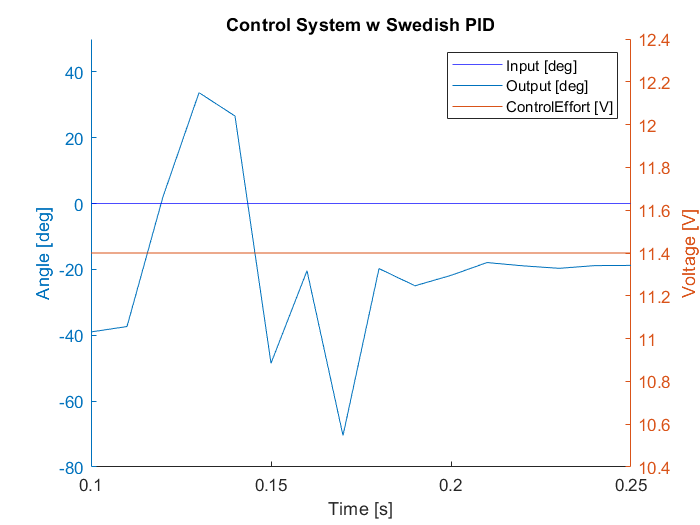

clf;
hold on
yyaxis left
yline(0,'b')
plot(t_Y_SVPID,output_Y_SVPID)
ylabel('Angle [deg]')
xlabel('Time [s]')
ylim([-80 50])
xlim([0.1 0.25])

yyaxis right
plot(t_Y_SVPID,CE_Y_SVPIDC)
ylabel('Voltage [V]')
title('Control System w Swedish PID')
legend('Input [deg]','Output [deg]','ControlEffort [V]')

hold off